Fano plane image from Wikipedia:

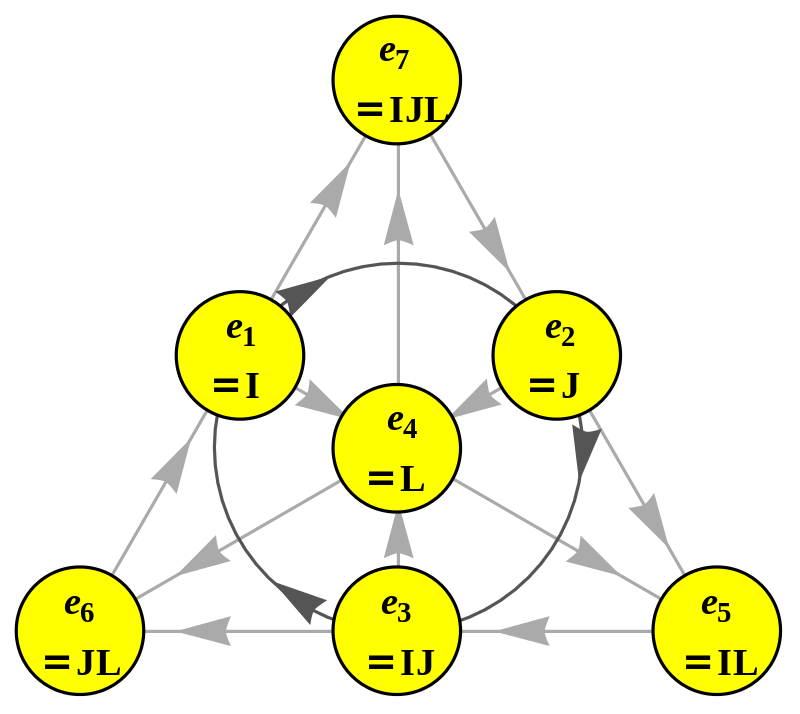

## Cayley-Dickson construction for Octonions


$$(1,0),(i,0),(j,0),(k,0),(0,1),(0,i),(0,j),(0,k)$$


Where a product is defined by:


$$(a,b)(c,d) = (ac-d^*b,da+bc^*)$$


function [DirectProductAB,DotProductAB,CrossProductAB] = octonionProduct(A,B)

validateattributes(A,{'numeric','sym'},{'nonempty'})
validateattributes(B,{'numeric','sym'},{'nonempty'})

if numel(A) ~= 8 || numel(B) ~= 8
    error('Input vectors must have eight elements each.')
end

O = makeOctonions;

octA = 0;
octB = 0;
for k = 1:8
    octA = octA + A(k)*O(:,:,k);
    octB = octB + B(k)*O(:,:,k);
end
octAB = CayleyDickson(octA,octB);

DirectProductAB = sym([]);
for k = 1:8
    M = octAB.*O(:,:,k);
    M = M(M~=0);
    DirectProductAB(k) = M(1);
end

E = subs(subs(DirectProductAB,A(1),0),B(1),0);
DotProductAB = -E(1);
CrossProductAB = E(2:end);
end

function DirProd = CayleyDickson(A,B)
a = A(:,1:4);
b = A(:,5:8);
c = B(:,1:4);
d = B(:,5:8);
C = a*c - d'*b;
D = d*a + b*(c');
DirProd = [C,D];
end